# A simulation of a decoy BB84 satellite pass

## 1. Choose parameters

wavelength=780;                                                            %wavelength is measured in nm
transmitter_telescope_diameter=0.1;                                        %diameters are measured in m
orbit_data_file_location='500kmSSOrbitLLAT.txt';                              %orbits are described by files containing latitude, longitude, altitude and time stamps. These are in the 'orbit modelling resources' folder
receiver_telescope_diameter=1;                                           
time_gate_width=1E-10;                                                      %times are measured in s
spectral_filter_width=10;                                                  %consistemt with wavelength, spectral width is measured in nm
mean_photon_numbers = [0.7,0.1,0];                                                        %mean photon numbers
state_probabilities = [0.75,0.25,0.25];                                                    %state probabilities

## 2. Construct components

%2.1 Satellite
%2.1.1 Source
Transmitter_Source=components.Source(wavelength,...
                          'MPN_Signal',mean_photon_numbers(1),...
                          'MPN_Decoy',mean_photon_numbers(2),...
                          'Probability_Signal',state_probabilities(1),...
                          'Probability_Decoy',state_probabilities(2));                                       %we use default values to simplify this example

%2.1.2 Transmitter telescope
Transmitter_Telescope=components.Telescope(transmitter_telescope_diameter);           %do not need to specify wavelength as this will be set by satellite object

%2.1.3 Construct satellite
SimSatellite=nodes.Satellite(Transmitter_Telescope,...
    'OrbitDataFileLocation',orbit_data_file_location,...
    'Source',Transmitter_Source);

%2.2 Ground station
%2.2.1 Detector
Detector=components.Detector(wavelength,Transmitter_Source.repetition_rate,time_gate_width,spectral_filter_width,'Preset','Perfect');
%need to provide repetition rate in order to compute QBER and loss due to
%time gating

%2.2.2 Receiver telescope
Receiver_Telescope=components.Telescope(receiver_telescope_diameter,'Wavelength',wavelength);

%2.2.3 construct ground station, use Heriot-Watt as an example
SimGround_Station=nodes.GroundStation(Receiver_Telescope,...
                                'Detector',Detector,...
                                'LLA',[55.909723, -3.319995,10],...
                                'Name','Heriot-Watt');

## 3 run and plot simulation

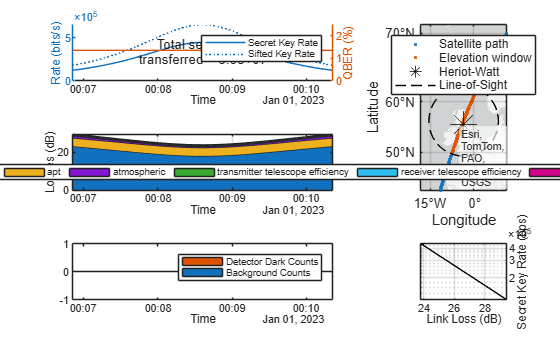

%3.1 run simulation
Result=nodes.qkdPassSimulation(SimGround_Station,SimSatellite,protocol.DecoyBB84);
%3.2 plot results
plot(Result);